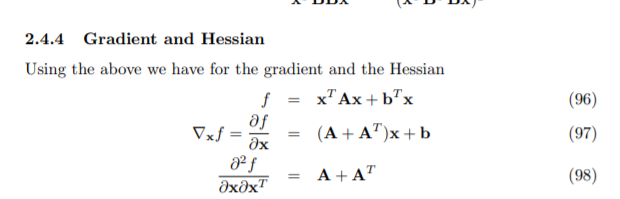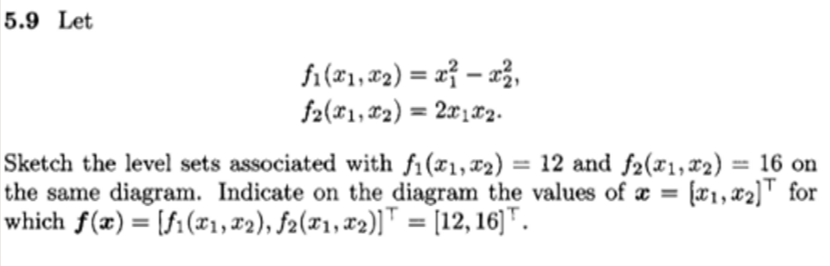

f1 = @(x1,x2) x1^2 - x2^2;
f2 = @(x1,x2) 2*x1 * x2;

syms x1 x2

x2 = solve (f1(x1,x2)==12,x2)

$$x2 = \left(\begin{array}{c} \sqrt{{x_{1}}^{2}-12}\\ -\sqrt{{x_{1}}^{2}-12} \end{array}\right)$$

fplot(x2)

hold on
syms x1 x2

x2 = solve (f2(x1,x2)==16,x2)

$$x2 = \frac{8}{x_{1}}$$

fplot(x2)

syms x1 x2 
[x1 x2] = solve(f1(x1,x2)==12,f2(x1,x2)==16,[x1 x2])

$$x1 = \left(\begin{array}{c} -4\\ 4\\ 2\,\mathrm{i}\\ -2\,\mathrm{i} \end{array}\right)$$

$$x2 = \left(\begin{array}{c} -2\\ 2\\ -4\,\mathrm{i}\\ 4\,\mathrm{i} \end{array}\right)$$

x1 = real(x1)

$$x1 = \left(\begin{array}{c} -4\\ 4\\ 0\\ 0 \end{array}\right)$$

x2 = real(x2)

$$x2 = \left(\begin{array}{c} -2\\ 2\\ 0\\ 0 \end{array}\right)$$

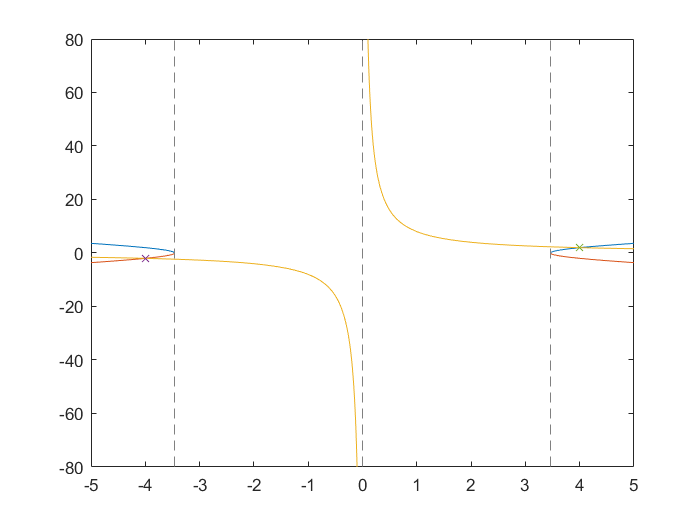


plot(x1(1),x2(1),"x")
plot(x1(2),x2(2),"x")

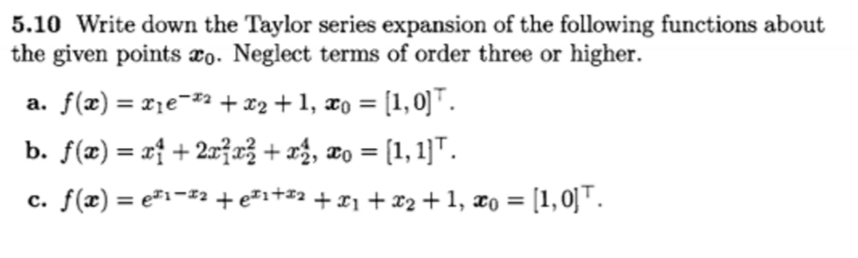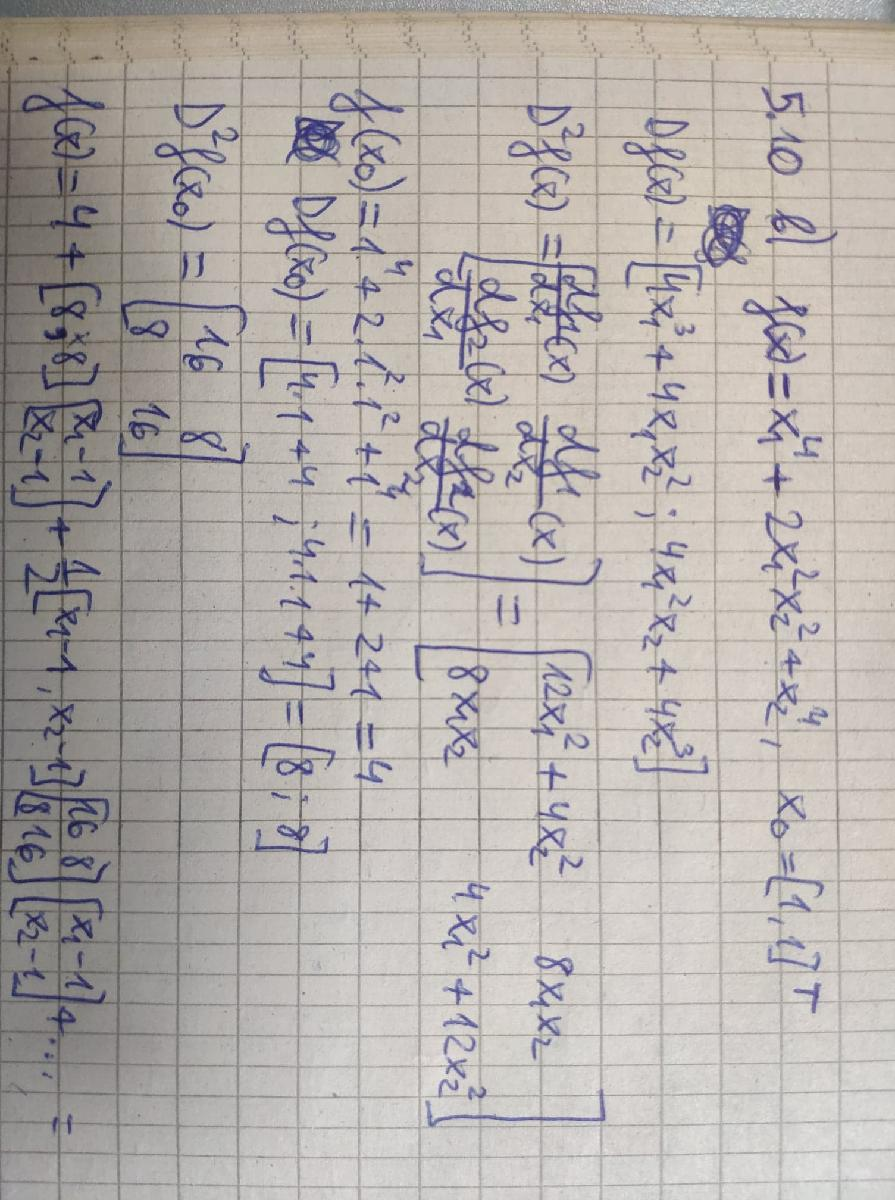

[https://mathinsight.org/taylors_theorem_multivariable_introduction](https://mathinsight.org/taylors_theorem_multivariable_introduction)

Let $x\in \Omega '$, then $x\in \Omega$ and therefore $f\left(x^\ast  \right)\le f\left(x\right)$. Hence, $x^\ast $ is a global minimizer of *f* over $\Omega '$.

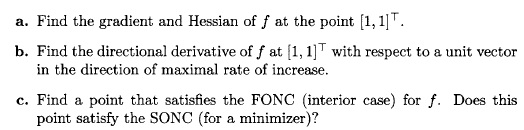

## a)

The gradient $\nabla f$ of $f$ is the transpose of the first derivative $\mathit{Df}$. 

The function exists in$R^2$, which implies that the first derivate consists of two partial derivatives:

 
$$\text{Df}\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial }{\partial x_1 }f\left(x\right) & \frac{\partial }{\partial x_2 }f\left(x\right)
\end{array}\right\rbrack$$


%a
f = @(x) x'*[1 2; 4 7]*x + x' *[3;5] + 6;
x0 = [1;1]

x0 =        1       
       1       



% First derivative (gradient)
syms x1 x2
df1_x1 = diff(f([x1; x2]),x1);
df1_x2 = diff(f([x1; x2]),x2);
Df = [df1_x1 df1_x2]

$$Df = \left(\begin{array}{cc} x_{1}+2\,x_{2}+\bar{x_{1}}+4\,\bar{x_{2}}+3 & 4\,x_{1}+7\,x_{2}+2\,\bar{x_{1}}+7\,\bar{x_{2}}+5 \end{array}\right)$$

gradient = Df'

$$gradient = \left(\begin{array}{c} x_{1}+4\,x_{2}+\bar{x_{1}}+2\,\bar{x_{2}}+3\\ 2\,x_{1}+7\,x_{2}+4\,\bar{x_{1}}+7\,\bar{x_{2}}+5 \end{array}\right)$$

The Hessian is the second derivative of *f*, which conists of four partical derivatives:


$$D^2 f\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial^2 }{\partial x_1^2 }f\left(x\right) & \frac{\partial^2 }{\partial x_2 x_1 }f\left(x\right)\\
\frac{\partial^2 }{\partial x_1 x_2 }f\left(x\right) & \frac{\partial^2 }{\partial x_2^2 }f\left(x\right)
\end{array}\right\rbrack$$


% Second order derivative (hessian)
syms x1 x2
df2_x1_x1 = diff(f([x1; x2]),x1,x1);
df2_x1_x2 = diff(f([x1; x2]),x1,x2);
df2_x2_x1 = diff(f([x1; x2]),x2,x1);
df2_x2_x2 = diff(f([x1; x2]),x2,x2);
D2f = [df2_x1_x1 df2_x2_x1; df2_x1_x2 df2_x2_x2]

$$D2f = \left(\begin{array}{cc} 2 & 6\\ 6 & 14 \end{array}\right)$$



%b
% The directional derivative in x0 can then be found
gradient_fnc = matlabFunction(gradient);
norm(gradient_fnc(1,1))

ans =     3578/131   


## c)

The FONC requires the gradient to be zero:


$$\nabla f(x)=0$$


This is found by solving the equation:


$$\left\lbrack \begin{array}{c}
2 & 6\\
6 & 14
\end{array}\right\rbrack \mathbf{x}+\left\lbrack \begin{array}{c}
3\\
5
\end{array}\right\rbrack=0$$


Which corresponds to solving the matrix system:


$$\left\lbrack \begin{array}{cccc}
2 & 6 & 3 & 0\\
6 & 14 & 5 & 0
\end{array}\right\rbrack \sim \left\lbrack \begin{array}{cccc}
1 & 0 & -1\ldotp 5 & 0\\
0 & 1 & 1 & 0
\end{array}\right\rbrack \longrightarrow x=\left\lbrack \begin{array}{c}
1\ldotp 5\\
-1
\end{array}\right\rbrack$$


The only point satisfying the FONC is therefore $x={\left\lbrack \begin{array}{cc}
1\ldotp 5 & -1
\end{array}\right\rbrack }^T$. 

A = [2 6; 6 14]; %(D2f)
B = [3; 5];
EQ = [0; 0];
rref([A B EQ])

ans =        1              0             -3/2            0       
       0              1              1              0       


The SONC requires the determinant of the Hessian to be non-negative.


$$\mathrm{det}\left(D^2 f\left(x\right)\right)\ge 0$$


det(A)

ans =       -8       


There are therefore no points satisfying the SONC.

## Exercise 6.10

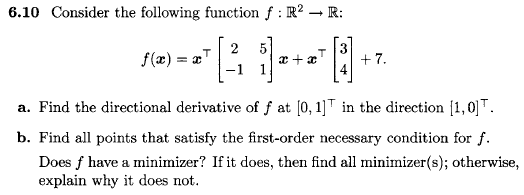

f = @(x) x'*[2 5; -1 1]*x+x'*[3; 4]+7;

## a)

The directional derivative of *f* in a given point and in a given direction is found by determining the expression for the gradient of *f*, then determining the value of the gradient in the given point and finally determining the value in a given direction by multiplying the directional vector.

The gradient of *f* is:


$$\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_1 }f\left(x\right)\\
\frac{\partial }{\partial x_2 }f\left(x\right)
\end{array}\right\rbrack$$


syms x1 x2
x = [x1; x2];
gradient = [diff(f(x),x1) diff(f(x),x2)]

$$gradient = \left(\begin{array}{cc} 2\,x_{1}+5\,x_{2}+2\,\bar{x_{1}}-\bar{x_{2}}+3 & x_{2}-x_{1}+5\,\bar{x_{1}}+\bar{x_{2}}+4 \end{array}\right)$$

gradient_fnc = matlabFunction(gradient);
x0 = [0;1];
x0_grad = gradient_fnc(x0(1),x0(2))'

x0_grad =        7       
       6       


Applying the direction $\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$by:


$$d^T \ast \nabla f\left(x\right)$$



$$\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \ast \nabla f\left(\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \right)=7$$


dir = [1; 0];
dir_der = dir'*x0_grad

dir_der =        7       


## b)

A minimizer point must satisfy the FONC, which requires the gradient to be zero:


$$\nabla f(x)=0$$


This is solved by solving the augmented matrix:


$$\left\lbrack \begin{array}{cccc}
4 & 4 & 3 & 0\\
4 & 2 & 4 & 0
\end{array}\right\rbrack \sim \left\lbrack \begin{array}{cccc}
1 & 0 & 1\ldotp 25 & 0\\
0 & 1 & -0\ldotp 5 & 0
\end{array}\right\rbrack \longrightarrow x=\left\lbrack \begin{array}{c}
-1\ldotp 25\\
0\ldotp 5
\end{array}\right\rbrack$$


rref([4 4 3 0; 4 2 4 0])

ans =        1              0              5/4            0       
       0              1             -1/2            0       


The only point satisfying the FONC is therefore $x={\left\lbrack \begin{array}{cc}
-1\ldotp 25 & 0\ldotp 5
\end{array}\right\rbrack }^T$. 

For the point to be a minimizer, the SONC must also be satisfied:


$$det(D^2f(x))\geq0$$


% Second order derivative
syms x1 x2
x = [x1; x2];
df2_x1_x1 = diff(f(x),x1,x1);
df2_x1_x2 = diff(f(x),x1,x2);
df2_x2_x1 = diff(f(x),x2,x1);
df2_x2_x2 = diff(f(x),x2,x2);
D2f = [df2_x1_x1 df2_x2_x1; df2_x1_x2 df2_x2_x2]

$$D2f = \left(\begin{array}{cc} 4 & 4\\ 4 & 2 \end{array}\right)$$

det(D2f)

$$ans = -8$$

$$V = \left(\begin{array}{cc} \frac{1}{4}-\frac{\sqrt{17}}{4} & \frac{\sqrt{17}}{4}+\frac{1}{4}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 3-\sqrt{17} & 0\\ 0 & \sqrt{17}+3 \end{array}\right)$$

There are therefore no points satisfying the SONC. The function *f* therefore does not have a minimizer.

## Exercise 6.11

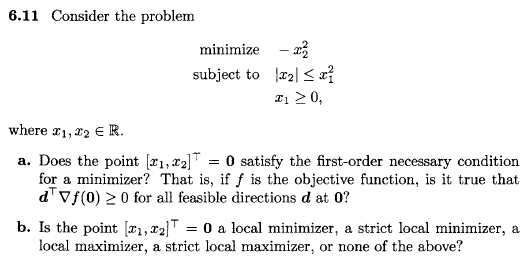

The objective function *f* is given by:


$$f\left(x\right)=-{x_2 }^2$$


f = @(x2) -x2^2 

f = function_handle with value:
    @(x2)-x2^2


## a)

The gradient of *f* is given by:


$$\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_1 }f\left(x\right)\\
\frac{\partial }{\partial x_2 }f\left(x\right)
\end{array}\right\rbrack$$


syms x2
gradient = [diff(f(x2),x1) diff(f(x2),x2)]

$$gradient = \left(\begin{array}{cc} 0 & -2\,x_{2} \end{array}\right)$$

gradient_fnc = matlabFunction(gradient);

The gradient in the point $x=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$:


$$\nabla f\left(\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


x0 = [0; 0];
gradient_fnc(x0(2))

ans =        0              0       


Any feasible direction *d, *will satisfy the FONC;


$$d^T \nabla f\left(0\right)=0$$


## b)

$\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =0$ is a local maximizer because $f\left(0\right)=0$, while every feasible *x* satisfies $f\left(x\right)\le 0$. The point is not a strict local maximizer since for any *x* of the form $x=\left\lbrack \begin{array}{c}
x_1 \\
0
\end{array}\right\rbrack$, $f\left(x\right)=0=f\left(0\right)$.

$\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =0$ is not a local minimizer because for any point *x* of the form $x=\left\lbrack \begin{array}{c}
x_1 \\
x_1^2 
\end{array}\right\rbrack ,x_1 >0$, it is given that $f\left(x\right)=-x_1^4 <0$. Since 0 is not a local minimizer, it is not a strict local minimizer.

## Exercise 6.20

A heartbeat sensor is located at position x

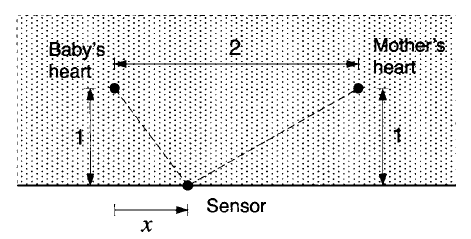

The energy of the heartbeat signal measured by the sensor is the reciprocal of the squared distance from the source (baby's heart or mother's heart). Find the position of the sensor that maximizes the signal-to-interference ratio, which is the ratio of the signal energy from the baby's heart to the signal energy from the mother's heart.

The squared distance to the hearts are given by:


$${d^2 }_{\mathrm{baby}} ={\left(\sqrt{1^2 +x^2 }\right)}^2 =1+x^2$$



$${d^2 }_{\mathrm{mother}} ={\left(\sqrt{1^2 +{\left(2-x\right)}^2 }\right)}^2 =1+{\left(2-x\right)}^2$$


The SNR as a function of the sensor placement x, is then given by:

f = @(x) (1 / (1+x^2)) / (1/(1+(2-x)^2));

This is the objective function to maximize.

The gradient of *f* is:

syms x
Df = simplify(diff(f(x),x))

$$Df = -\frac{4\,\left(-x^{2}+2\,x+1\right)}{{\left(x^{2}+1\right)}^{2}}$$

gradient_fnc = matlabFunction(Df);

The maximum and minimum points are found by solving the FONC:


$$\nabla \text{ }f\left(x\right)=0$$


x = solve(gradient_fnc(x)==0,x)

$$x = \left(\begin{array}{c} 1-\sqrt{2}\\ \sqrt{2}+1 \end{array}\right)$$

Finding the maximum and minimum points from the solutions:

max = double(f(x(1)))

max =     1189/204   


min = double(f(x(2)))

min =      204/1189  


The optimal solution for the placement of the sensor is therefore:


$$f\left(1-\sqrt{2}\right)=5\ldotp 8284>f\left(1+\sqrt{2}\right)=0\ldotp 1716$$



$$x=1-\sqrt{2}$$


## Linear Algebra and Its Applications sec. 7.1

## Exercise 7.9


$$3x_1^2 -4x_1 x_2 +6x_2^2$$


Constructing the quadratic form:


$$x^T \mathrm{Ax}=\left\lbrack \begin{array}{c}
x_1  & x_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
3 & -2\\
-2 & 6
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


A = [3 -2; -2 6];

Finding the eigenvalue and normalized eigenvectors:

[V, D] = eig(A)

V =    -2584/2889     -1292/2889  
   -1292/2889      2584/2889  


D =        2              0       
       0              7       


A may be diagonalized as:


$$A={\mathrm{PDP}}^{-1}$$


Where:


$$P=\left\lbrack \begin{array}{c}
u_1  & u_2 
\end{array}\right\rbrack ,D=\left\lbrack \begin{array}{c}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$$


The change of variables $x=\mathrm{Py}$ can then be found by:


$$x^T \mathrm{Ax}={\left(\mathrm{Py}\right)}^T A\left(\mathrm{Py}\right)=y^T P^T \mathrm{APy}=y^T \mathrm{Dy}=\left\lbrack \begin{array}{c}
y_1  & y_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack$$


syms y1 y2
y = [y1; y2];
y'*D*y

$$ans = 2\,y_{1}\,\bar{y_{1}}+7\,y_{2}\,\bar{y_{2}}$$

## Exercise 7.10


$$9x_1^2 -8x_1 x_2 +3x_2^2$$


Constructing the quadratic form:


$$x^T \text{Ax}=\left\lbrack \begin{array}{c}
x_1  & x_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
9 & -4\\
-4 & 3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


A = [9 -4; -4 3];
[V, D] = eig(A)

V =    -1292/2889     -2584/2889  
   -2584/2889      1292/2889  


D =        1              0       
       0             11       



syms y1 y2
y = [y1; y2];
y'*D*y

$$ans = y_{1}\,\bar{y_{1}}+11\,y_{2}\,\bar{y_{2}}$$

## Exercise 7.11


$$2x_1^2 -10x_1 x_2 +2x_2^2$$


Constructing the quadratic form:


$$x^T \text{Ax}=\left\lbrack \begin{array}{c}
x_1  & x_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
2 & -5\\
-5 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


A = [2 5; 5 2];
[V, D] = eig(A)

V =     -985/1393       985/1393  
     985/1393       985/1393  


D =       -3              0       
       0              7       



syms y1 y2
y = [y1; y2];
y'*D*y

$$ans = 7\,y_{2}\,\bar{y_{2}}-3\,y_{1}\,\bar{y_{1}}$$

## Exercise 7.12


$$-5x_1^2 +4x_1 x_2 -2x_2^2$$


Constructing the quadratic form:


$$x^T \text{Ax}=\left\lbrack \begin{array}{c}
x_1  & x_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-5 & 2\\
2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


A = [-5 2; 2 -2];
[V, D] = eig(A)

V =    -2584/2889     -1292/2889  
    1292/2889     -2584/2889  


D =       -6              0       
       0             -1       



syms y1 y2
y = [y1; y2];
y'*D*y

$$ans = -6\,y_{1}\,\bar{y_{1}}-y_{2}\,\bar{y_{2}}$$